# Práctica 1 - Modelación y Simulación de un Sistema Dinámico No Lineal

**Curso: Sistemas Lineales**

**Universidad EAFIT**

**Marzo 15 de 2026**

**David Vivas Rojas, David Naranjo López**

## 1. Introducción

El Virus de Inmunodeficiencia Humana tipo 1 (VIH-1) es uno de los patógenos más estudiados desde la perspectiva de la dinámica de sistemas biológicos. Su evolución dentro del organismo humano puede describirse mediante ecuaciones diferenciales ordinarias no lineales que capturan la interacción entre células inmunes sanas, células infectadas y partículas virales libres.

El modelo empleado en esta práctica es el modelo reducido de segundo orden propuesto por Barão y Lemos (2007), derivado mediante una aproximación de perturbación singular a partir de un modelo de tercer orden. Esta simplificación es válida porque la dinámica del virus libre (x₃) es significativamente más rápida que la de las poblaciones celulares, lo que permite asumir que x₃ se encuentra siempre en cuasi-equilibrio respecto a x₂. El cociente x₂/x₃ converge a un valor constante aproximadamente en 2-3 días, mientras la dinámica dominante ocurre en una escala de semanas a meses.

El modelo resultante es un sistema dinámico no lineal de orden 2, en tiempo continuo, con una entrada de control que representa la eficacia del tratamiento antirretroviral. Este tipo de modelos es de gran relevancia tanto en biología matemática como en el diseño de estrategias de control para terapias médicas.

**Pregunta de investigación:** ¿Cómo afectan la eficacia del tratamiento antirretroviral (entrada u), las condiciones iniciales y los parámetros del modelo a la dinámica de la concentración de células CD4+T infectadas (x₂), y en qué medida puede el tratamiento farmacológico reducir la carga de infección hacia el equilibrio sano?

**Objetivos de la práctica:**

- Describir formalmente el modelo matemático en variables de estado.

- Implementar y verificar el modelo en MATLAB comparando con resultados conocidos.

- Analizar el comportamiento del sistema ante diversas entradas.

- Estudiar el efecto del cambio de parámetros sobre la dinámica.

## 2. Métodos

Los pasos realizados en esta práctica son:

- Describir el modelo matemático en variables de estado: ecuaciones, variables, parámetros, unidades y puntos de equilibrio.

- Implementar el sistema de EDOs en MATLAB usando una función anónima compatible con `ode45`.

- Verificar el modelo: simular la infección desde condiciones de persona sana y contrastar la respuesta con los resultados reportados en Barão & Lemos (2007), incluyendo los valores de equilibrio y la forma cualitativa de la respuesta.

- Simular el sistema con tres tipos de entrada (escalón, sinusoidal, pulso) y analizar la respuesta de la salida y = x₂.

- Simular el sistema con el cambio de dos parámetros del modelo (β y μ), variando cada uno en cinco valores y registrando características de la respuesta temporal.

- Interpretar y discutir todos los resultados obtenidos.

## 2.1 Descripción del Modelo Matemático en Variables de Estado

El modelo reducido de la infección por VIH-1, obtenido mediante la aproximación de perturbación singular sobre el modelo completo de tercer orden (Barão y Lemos, 2007), queda descrito por el siguiente sistema de ecuaciones diferenciales:


$$\dot{x}_1 = s - d\,x_1 - (1 - u)\frac{\beta k}{c}\,x_1 x_2$$



$$\dot{x}_2 = (1 - u)\frac{\beta k}{c}\,x_1 x_2 - \mu\,x_2$$


Este sistema corresponde a la **ecuación (3)** del artículo de referencia.

## 2.1.1 Variables de Estado

El vector de estado es $\mathbf{x} = [x_1,\; x_2]^T \in \mathbb{R}^2$, donde:

- **x₁(t)** : Concentración de células CD4+T sanas [células/mm³].

- **x₂(t)** : Concentración de células CD4+T infectadas [células/mm³].

## 2.1.2 Variable de Entrada


$$u(t) \in [0,\; u_{\max}), \quad u_{\max} < 1$$


- **u(t)** : Eficacia combinada del tratamiento antirretroviral [adimensional]. u = 0 corresponde a ausencia de medicamento; u → 1 corresponde a una eficacia del 100% (no alcanzable con los fármacos actuales).

## 2.1.3 Parámetros del Modelo

## 2.1.4 Definición de Parámetros Numéricos

% Parámetros del modelo (Tabla 1, Barão & Lemos, 2007)
s    = 10;        % Tasa de producción de células sanas      [células/(mm³·día)]
d    = 0.02;      % Tasa de muerte natural de células sanas  [día⁻¹]
beta = 2.4e-5;    % Coeficiente de infección                 [mm³/día]
k    = 100;       % Tasa de liberación de viriones           [día⁻¹]
c    = 2.4;       % Tasa de aclaramiento del virus libre     [día⁻¹]
mu   = 0.24;      % Tasa de muerte de células infectadas     [día⁻¹]

% Término compuesto del modelo reducido: β·k/c [mm³⁻¹·día⁻¹]
bkc = beta * k / c;
fprintf('\nTérmino compuesto β·k/c = %.6e [mm³⁻¹·día⁻¹]\n', bkc);


Término compuesto β·k/c = 1.000000e-03 [mm³⁻¹·día⁻¹]


## 2.1.5 Variable de Salida

Se selecciona como salida de interés:


$$y(t) = x_2(t)$$


La concentración de células CD4+T infectadas es el indicador clínico más directo de la progresión de la infección y está ligada a la carga viral libre mediante la relación de perturbación singular x₃ = (k/c)·x₂.

## 2.1.6 Puntos de Equilibrio

% Equilibrio sano (u = 0, persona no infectada)
xeq1 = [s/d; 0];

% Equilibrio infectado crónico (u = 0)
xeq2 = [mu*c/(beta*k);  s/mu - d*c/(beta*k)];

Equilibrio = ["Sano"; "Infectado"];
x1 = [xeq1(1); xeq2(1)];
x2 = [xeq1(2); xeq2(2)];

disp(table(Equilibrio, x1, x2))

    Equilibrio     x1       x2  
    ___________    ___    ______

    "Sano"         500         0
    "Infectado"    240    21.667



fprintf('Nota: Barão & Lemos (2007) reportan [240.0, 21.667] → concordancia exacta.\n');

Nota: Barão & Lemos (2007) reportan [240.0, 21.667] → concordancia exacta.


## 2.1.7 No Linealidad e Implicaciones para la Simulación

El término x₁x₂ representa la interaccion directa entre celulas sanas e infectadas, como es el producto de las dos variables de estado esto hace al sistema no lineal: la velocidad de infección no depende solo del virus ni solo de las células, sino de ambos a la vez. La entrada u aparece multiplicada por x₁x₂, por lo que la efectividad del tratamiento depende del estado actual del sistema. Una consecuencia del análisis de controlabilidad no lineal demostrada en el artículo es que, una vez que x₂ > 0, no es posible llevarlo a cero mediante el tratamiento farmacológico disponible.

## 3. Resultados

## 3.1 Verificación del Modelo

Para verificar la implementación se reproduce el escenario de la **Figura 1** de Barão & Lemos (2007): una persona sana que es infectada con una concentración inicial de 1 virión/mm³ y no recibe tratamiento (u = 0).

**Derivación de las condiciones iniciales:** En el modelo completo de 3er orden, la condición inicial corresponde a la persona sana (x₁ = s/d = 500, x₂ = 0) más 1 copia de virus por mm³ (x₃ = 1). En el modelo reducido, la relación de cuasi-equilibrio establece:


$$x_3 = \frac{k}{c}\,x_2 \quad \Rightarrow \quad x_2(0) = \frac{c}{k}\,x_3(0)
 = \frac{2.4}{100}\times 1 = 0.024 \text{ células/mm}^3$$


% --- Condiciones iniciales ---
x1_0 = s / d;        % Persona sana: x1(0) = 500 células/mm³
x2_0 = (c/k) * 1;   % 1 virión/mm³ traducido al modelo reducido: x2(0) = 0.024
x0   = [x1_0; x2_0];

CondicionInicial = ["x1(0)"; "x2(0)"];

disp(table(CondicionInicial, x0))

    CondicionInicial     x0  
    ________________    _____

        "x1(0)"           500
        "x2(0)"         0.024



% --- Definición del sistema de EDOs ---
% El modelo se implementa como función anónima f(t, x, u_val).
% Con u = 0 (sin tratamiento) para la verificación.
u_verif = 0;

vih_ode = @(t, x, u_val) [
    s  -  d*x(1)  -  (1 - u_val)*bkc*x(1)*x(2);    % ẋ₁
    (1 - u_val)*bkc*x(1)*x(2)  -  mu*x(2)           % ẋ₂
];

% --- Parámetros de simulación ---
t_end  = 500;    % 500 días: suficiente para alcanzar el equilibrio crónico
tspan  = [0, t_end];
opts   = odeset('RelTol', 1e-8, 'AbsTol', 1e-10, 'MaxStep', 1.0);

% --- Simulación ---
[t_v, X_v] = ode45(@(t,x) vih_ode(t, x, u_verif), tspan, x0, opts);

x1_v = X_v(:, 1);             % Células CD4+T sanas     [células/mm³]
x2_v = X_v(:, 2);             % Células CD4+T infectadas [células/mm³]
x3_v = (k/c) .* x2_v;        % Carga viral reconstruida [copias/mm³]

% --- Verificación numérica contra equilibrio teórico ---
fprintf('\n--- Verificación: valores al final de la simulación (t = %d días) ---\n', t_end);


--- Verificación: valores al final de la simulación (t = 500 días) ---


fprintf('x1(%d) = %.4f  | x1* teórico = %.4f  | Error = %.4f%%\n', ...
        t_end, x1_v(end), xeq2(1), abs(x1_v(end)-xeq2(1))/xeq2(1)*100);

x1(500) = 239.9964  | x1* teórico = 240.0000  | Error = 0.0015%


fprintf('x2(%d) = %.4f  | x2* teórico = %.4f  | Error = %.4f%%\n', ...
        t_end, x2_v(end), xeq2(2), abs(x2_v(end)-xeq2(2))/xeq2(2)*100);

x2(500) = 21.6692  | x2* teórico = 21.6667  | Error = 0.0119%


## 3.1.1 Gráficos de Verificación

La figura reproduce la estructura de la Figura 1 de Barão & Lemos (2007).

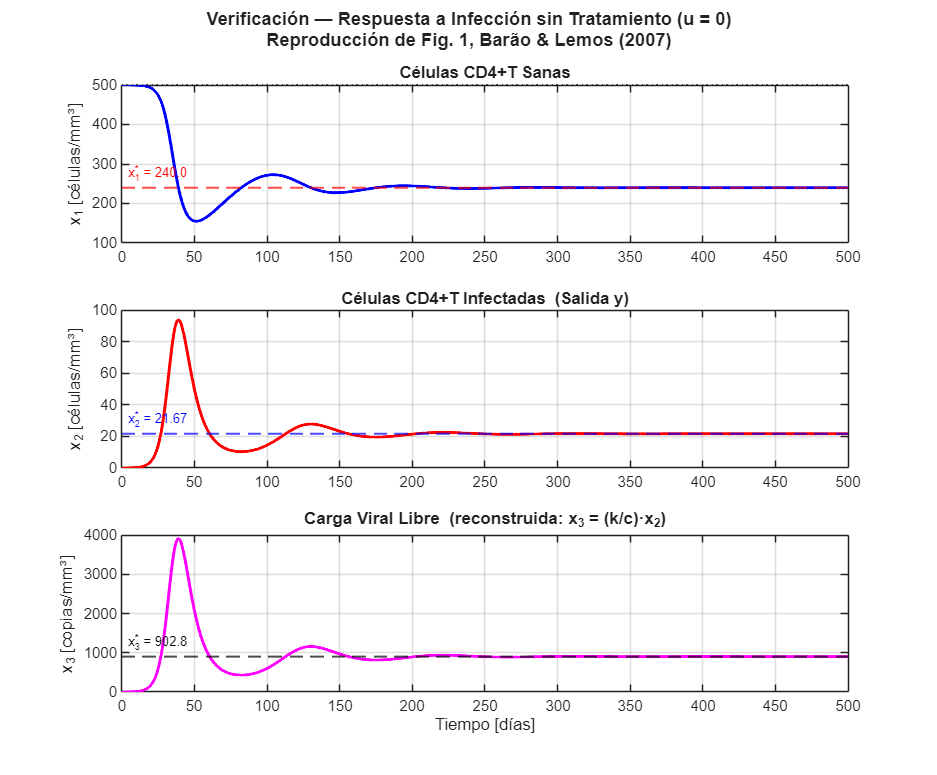

figure('Name','Verificación — Fig. 1 (Barão & Lemos, 2007)', ...
       'NumberTitle','off','Color','w','Position',[100 80 750 620]);

subplot(3,1,1);
plot(t_v, x1_v, 'b', 'LineWidth', 1.8); hold on;
yline(xeq2(1),'--r','LineWidth',1.2,'Label',sprintf('x_1^* = %.1f',xeq2(1)), ...
      'LabelHorizontalAlignment','left','FontSize',8);
yline(xeq1(1),':k','LineWidth',1.0,'Label','x_1^{sano} = 500', ...
      'LabelHorizontalAlignment','left','FontSize',8); hold off;
ylabel('x_1 [células/mm³]','FontSize',10);
title('Células CD4+T Sanas','FontSize',10,'FontWeight','bold');
xlim([0 t_end]); grid on; box on;

subplot(3,1,2);
plot(t_v, x2_v, 'r', 'LineWidth', 1.8); hold on;
yline(xeq2(2),'--b','LineWidth',1.2,'Label',sprintf('x_2^* = %.2f',xeq2(2)), ...
      'LabelHorizontalAlignment','left','FontSize',8); hold off;
ylabel('x_2 [células/mm³]','FontSize',10);
title('Células CD4+T Infectadas  (Salida y)','FontSize',10,'FontWeight','bold');
xlim([0 t_end]); grid on; box on;

subplot(3,1,3);
plot(t_v, x3_v, 'm', 'LineWidth', 1.8); hold on;
yline((k/c)*xeq2(2),'--k','LineWidth',1.2, ...
      'Label',sprintf('x_3^* = %.1f',(k/c)*xeq2(2)), ...
      'LabelHorizontalAlignment','left','FontSize',8); hold off;
ylabel('x_3 [copias/mm³]','FontSize',10);
xlabel('Tiempo [días]','FontSize',10);
title('Carga Viral Libre  (reconstruida: x_3 = (k/c)·x_2)', ...
      'FontSize',10,'FontWeight','bold');
xlim([0 t_end]); grid on; box on;

sgtitle({'Verificación — Respuesta a Infección sin Tratamiento (u = 0)'; ...
         'Reproducción de Fig. 1, Barão & Lemos (2007)'}, ...
         'FontSize',11,'FontWeight','bold');

## 3.1.2 Plano de Fase — Verificación de la Estabilidad

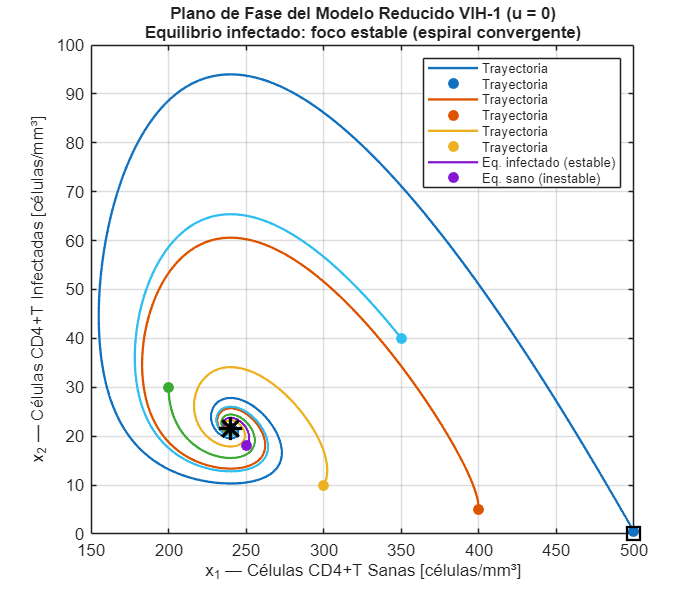

CI_pf = [500, 0.5; 400, 5.0; 300, 10.0; 250, 18.0; 200, 30.0; 350, 40.0];

figure('Name','Plano de Fase — Verificación de Estabilidad', ...
       'NumberTitle','off','Color','w','Position',[860 80 560 480]);

colores = lines(size(CI_pf,1)); hold on;
for i = 1:size(CI_pf,1)
    [~, X_i] = ode45(@(t,x) vih_ode(t,x,u_verif), [0 800], CI_pf(i,:)', opts);
    plot(X_i(:,1), X_i(:,2), 'Color', colores(i,:), 'LineWidth', 1.4);
    plot(X_i(1,1), X_i(1,2), 'o', 'Color', colores(i,:), ...
         'MarkerFaceColor', colores(i,:), 'MarkerSize', 6);
end
plot(xeq2(1), xeq2(2), 'k*', 'MarkerSize', 14, 'LineWidth', 2);
plot(xeq1(1), xeq1(2), 'ks', 'MarkerSize', 10, 'LineWidth', 2);
hold off;
xlabel('x_1 — Células CD4+T Sanas [células/mm³]','FontSize',10);
ylabel('x_2 — Células CD4+T Infectadas [células/mm³]','FontSize',10);
title({'Plano de Fase del Modelo Reducido VIH-1 (u = 0)'; ...
       'Equilibrio infectado: foco estable (espiral convergente)'}, ...
       'FontSize',10,'FontWeight','bold');
legend([repmat({'Trayectoria'},1,size(CI_pf,1)), ...
        {'Eq. infectado (estable)','Eq. sano (inestable)'}], ...
       'Location','northeast','FontSize',8);
grid on; box on;

## 3.1.3 Resumen Cuantitativo de la Verificación

A_eq = [-d - bkc*xeq2(2),  -bkc*xeq2(1);
         bkc*xeq2(2),        bkc*xeq2(1) - mu];
eig_vals = eig(A_eq);
fprintf('                    Simulado     Teórico    Error(%%)\n');

                    Simulado     Teórico    Error(%)


fprintf('x1* [céls/mm³]      %8.4f     %8.4f     %.4f%%\n', ...
        x1_v(end), xeq2(1), abs(x1_v(end)-xeq2(1))/xeq2(1)*100);

x1* [céls/mm³]      239.9964     240.0000     0.0015%


fprintf('x2* [céls/mm³]      %8.4f     %8.4f     %.4f%%\n', ...
        x2_v(end), xeq2(2), abs(x2_v(end)-xeq2(2))/xeq2(2)*100);

x2* [céls/mm³]       21.6692      21.6667     0.0119%


fprintf('Eigenvalores del Jacobiano en el equilibrio infectado:\n');

Eigenvalores del Jacobiano en el equilibrio infectado:


fprintf('  λ₁ = %.4f %+.4fj\n', real(eig_vals(1)), imag(eig_vals(1)));

  λ₁ = -0.0208 +0.0690j


fprintf('  λ₂ = %.4f %+.4fj\n', real(eig_vals(2)), imag(eig_vals(2)));

  λ₂ = -0.0208 -0.0690j


fprintf('Ref. (Tabla 2, Barão & Lemos 2007): -0.0208 ± 0.0690j\n');

Ref. (Tabla 2, Barão & Lemos 2007): -0.0208 ± 0.0690j


fprintf('Conclusión: foco estable (parte real < 0, parte imaginaria ≠ 0) ✓\n');

Conclusión: foco estable (parte real < 0, parte imaginaria ≠ 0) ✓


## 3.2 Simulación con Diversas Entradas

Se simulan tres tipos de entrada clínicamente relevantes partiendo del **equilibrio infectado crónico** (xeq2), que es el estado en que se encuentra un paciente antes de iniciar tratamiento. Esto permite observar claramente el efecto de cada forma de entrada sobre la dinámica de x₂ (salida de interés).

Las tres entradas utilizadas son:

- **Escalón (constante):** u(t) = 0 para t < 0; u(t) = 0.7 para t ≥ 0. Representa el inicio de un tratamiento antirretroviral sostenido con eficacia del 70%.

- **Sinusoidal:** u(t) = 0.5 + 0.4·sin(2π·t/365). Modela variaciones periódicas anuales en la adherencia o dosificación del tratamiento. La señal oscila entre 0.1 y 0.9, siempre dentro del rango físicamente admisible [0, 1).

- **Pulso:** u(t) = 0.85 para 50 ≤ t ≤ 200 días; u(t) = 0 en otro caso. Representa un ciclo de tratamiento intensivo de 150 días seguido de interrupción. Permite observar el rebote viral al suspender la terapia.

**Condiciones iniciales para todas las entradas:** Se parte del equilibrio infectado crónico (estado del paciente sin tratamiento).

x0_trat = xeq2;   % Condición inicial: equilibrio infectado [240; 21.667]

fprintf('\n--- Condiciones iniciales (simulación con entradas) ---\n');


--- Condiciones iniciales (simulación con entradas) ---


fprintf('x1(0) = %.4f células/mm³  (equilibrio infectado crónico)\n', x0_trat(1));

x1(0) = 240.0000 células/mm³  (equilibrio infectado crónico)


fprintf('x2(0) = %.4f células/mm³  (equilibrio infectado crónico)\n', x0_trat(2));

x2(0) = 21.6667 células/mm³  (equilibrio infectado crónico)



t_sim  = 500;      % Horizonte de simulación [días]
t_fine = linspace(0, t_sim, 5000);   % Vector de tiempo de alta resolución

## 3.2.1 Definición de las Señales de Entrada

% --- Entrada 1: Escalón ---
% Inicio del tratamiento en t = 0, eficacia constante del 70%.
u_esc  = 0.7;                        % Eficacia [adimensional]
u_step = @(t) u_esc .* (t >= 0);    % Función escalonada

% --- Entrada 2: Sinusoidal ---
% Período T = 365 días (ciclo anual), oscila entre 0.1 y 0.9.
A_sin   = 0.4;     % Amplitud [adimensional]
offset  = 0.5;     % Valor medio [adimensional]
T_sin   = 365;     % Período [días]
u_sin   = @(t) offset + A_sin .* sin(2*pi*t / T_sin);

% --- Entrada 3: Pulso ---
% Tratamiento intensivo entre los días 50 y 200 (duración: 150 días).
t_ini_p = 50;      % Inicio del pulso [días]
t_fin_p = 200;     % Fin del pulso [días]
u_pul   = 0.85;    % Eficacia durante el pulso [adimensional]
u_pulse = @(t) u_pul .* (t >= t_ini_p & t <= t_fin_p);

fprintf('\n--- Definición de Entradas ---\n');


--- Definición de Entradas ---


fprintf('Escalón:    u = %.2f  para t ≥ 0  (tratamiento sostenido)\n', u_esc);

Escalón:    u = 0.70  para t ≥ 0  (tratamiento sostenido)


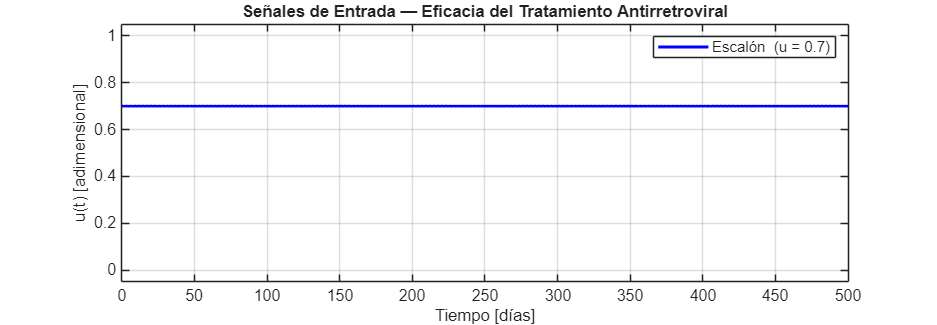

figure('Name','Entradas aplicadas al sistema VIH-1', ...
       'NumberTitle','off','Color','w','Position',[100 80 750 260]);

t_plot = linspace(0, t_sim, 2000);
plot(t_plot, u_step(t_plot),  'b',  'LineWidth', 1.8); hold on;
xlabel('Tiempo [días]', 'FontSize', 10);
ylabel('u(t) [adimensional]', 'FontSize', 10);
title('Señales de Entrada — Eficacia del Tratamiento Antirretroviral', ...
      'FontSize', 10, 'FontWeight', 'bold');
legend({'Escalón  (u = 0.7)'}, ...
       'Location', 'northeast', 'FontSize', 9);
ylim([-0.05, 1.05]); grid on; box on;

fprintf('Sinusoidal: u = %.1f + %.1f·sin(2π·t/%.0f)  → rango [%.1f, %.1f]\n', ...
        offset, A_sin, T_sin, offset-A_sin, offset+A_sin);

Sinusoidal: u = 0.5 + 0.4·sin(2π·t/365)  → rango [0.1, 0.9]


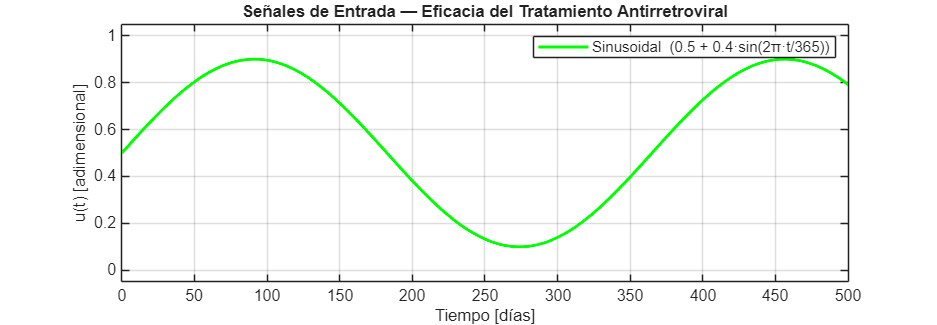

figure('Name','Entradas aplicadas al sistema VIH-1', ...
       'NumberTitle','off','Color','w','Position',[100 80 750 260]);

t_plot = linspace(0, t_sim, 2000);
plot(t_plot, u_sin(t_plot),   'g',  'LineWidth', 1.8);
xlabel('Tiempo [días]', 'FontSize', 10);
ylabel('u(t) [adimensional]', 'FontSize', 10);
title('Señales de Entrada — Eficacia del Tratamiento Antirretroviral', ...
      'FontSize', 10, 'FontWeight', 'bold');
legend({sprintf('Sinusoidal  (%.1f + %.1f·sin(2π·t/365))', offset, A_sin)}, ...
       'Location', 'northeast', 'FontSize', 9);
ylim([-0.05, 1.05]); grid on; box on;

fprintf('Pulso:      u = %.2f  para %d ≤ t ≤ %d días, u = 0 fuera\n', ...
        u_pul, t_ini_p, t_fin_p);

Pulso:      u = 0.85  para 50 ≤ t ≤ 200 días, u = 0 fuera


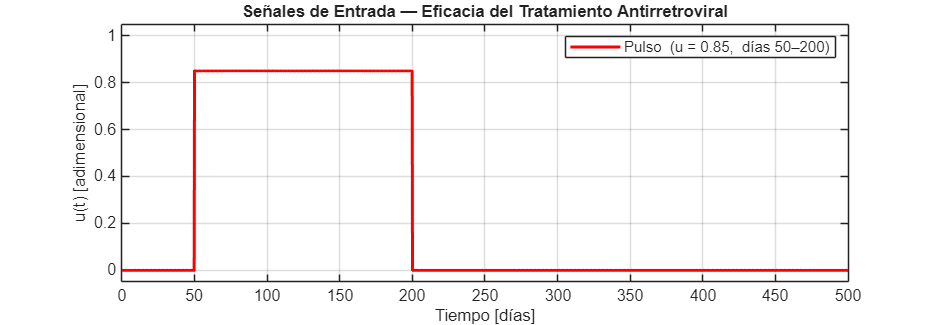

% --- Figura A: Señales de entrada ---
figure('Name','Entradas aplicadas al sistema VIH-1', ...
       'NumberTitle','off','Color','w','Position',[100 80 750 260]);

t_plot = linspace(0, t_sim, 2000);
plot(t_plot, u_pulse(t_plot), 'r',  'LineWidth', 1.8); hold off;
xlabel('Tiempo [días]', 'FontSize', 10);
ylabel('u(t) [adimensional]', 'FontSize', 10);
title('Señales de Entrada — Eficacia del Tratamiento Antirretroviral', ...
      'FontSize', 10, 'FontWeight', 'bold');
legend({sprintf('Pulso  (u = %.2f,  días %d–%d)', u_pul, t_ini_p, t_fin_p)}, ...
       'Location', 'northeast', 'FontSize', 9);
ylim([-0.05, 1.05]); grid on; box on;

## 3.2.2 Simulación de los Tres Casos

% ode45 para sistemas con entrada variable en el tiempo:
% se pasa la señal de entrada como función de t evaluada dentro del ODEs.

% --- Caso 1: Escalón ---
ode_step  = @(t,x) vih_ode(t, x, u_step(t));
[t1, X1]  = ode45(ode_step,  [0 t_sim], x0_trat, opts);

% --- Caso 2: Sinusoidal ---
ode_sinus = @(t,x) vih_ode(t, x, u_sin(t));
[t2, X2]  = ode45(ode_sinus, [0 t_sim], x0_trat, opts);

% --- Caso 3: Pulso ---
ode_pulse = @(t,x) vih_ode(t, x, u_pulse(t));
[t3, X3]  = ode45(ode_pulse, [0 t_sim], x0_trat, opts);

## 3.2.3 Gráficos — Respuesta ante las Tres Entradas

Figura A: la respuesta de la salida y = x₂(t) ante cada entrada, con tres subgráficos para comparación directa.

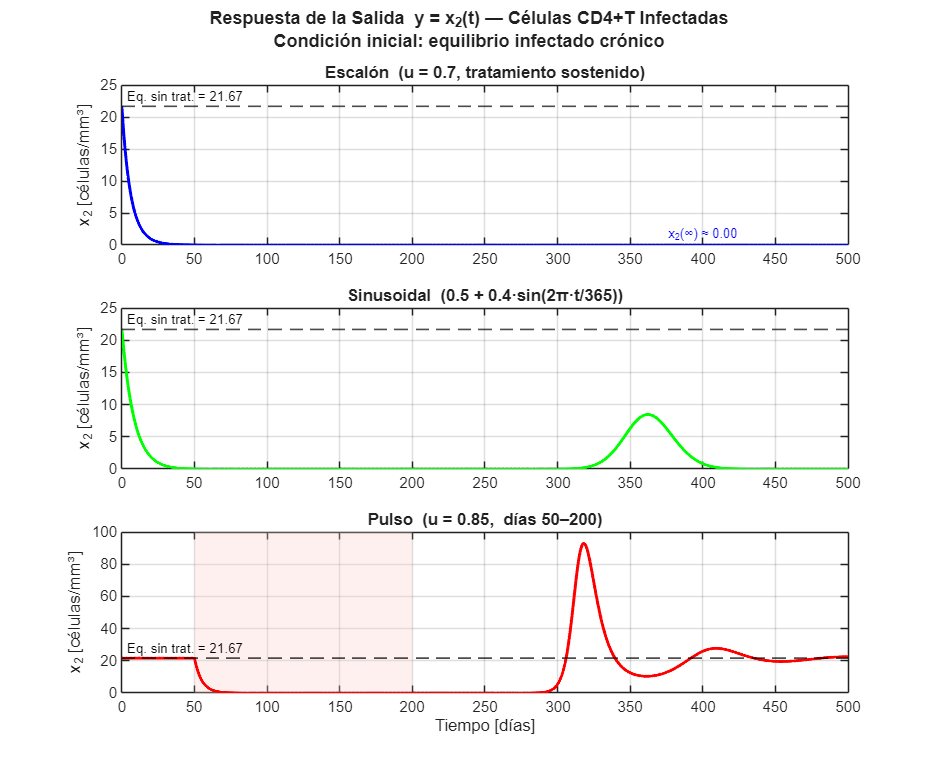

% --- Figura A: Respuesta de la salida y = x₂(t) ---
figure('Name','Respuesta del sistema VIH-1 ante diversas entradas', ...
       'NumberTitle','off','Color','w','Position',[100 380 750 620]);

% Referencia: equilibrio crónico sin tratamiento
y_eq_inf = xeq2(2);   % x2* = 21.667 células/mm³

% Subgráfico 1: Escalón
subplot(3,1,1);
plot(t1, X1(:,2), 'b', 'LineWidth', 1.8); hold on;
yline(y_eq_inf, '--k', 'LineWidth', 1.0, ...
      'Label', sprintf('Eq. sin trat. = %.2f', y_eq_inf), ...
      'LabelHorizontalAlignment', 'left', 'FontSize', 8);
hold off;
ylabel('x_2 [células/mm³]', 'FontSize', 10);
title('Escalón  (u = 0.7, tratamiento sostenido)', 'FontSize', 10, 'FontWeight', 'bold');
xlim([0 t_sim]); grid on; box on;
% Anotar el valor estacionario alcanzado
x2_ss_step = X1(end, 2);
text(t_sim*0.75, x2_ss_step + 1.5, sprintf('x_2(∞) ≈ %.2f', x2_ss_step), ...
     'FontSize', 8, 'Color', 'b');

% Subgráfico 2: Sinusoidal
subplot(3,1,2);
plot(t2, X2(:,2), 'g', 'LineWidth', 1.8); hold on;
yline(y_eq_inf, '--k', 'LineWidth', 1.0, ...
      'Label', sprintf('Eq. sin trat. = %.2f', y_eq_inf), ...
      'LabelHorizontalAlignment', 'left', 'FontSize', 8);
hold off;
ylabel('x_2 [células/mm³]', 'FontSize', 10);
title(sprintf('Sinusoidal  (%.1f + %.1f·sin(2π·t/365))', offset, A_sin), ...
      'FontSize', 10, 'FontWeight', 'bold');
xlim([0 t_sim]); grid on; box on;

% Subgráfico 3: Pulso
subplot(3,1,3);
plot(t3, X3(:,2), 'r', 'LineWidth', 1.8); hold on;
yline(y_eq_inf, '--k', 'LineWidth', 1.0, ...
      'Label', sprintf('Eq. sin trat. = %.2f', y_eq_inf), ...
      'LabelHorizontalAlignment', 'left', 'FontSize', 8);
% Sombreado de la ventana del pulso
xregion(t_ini_p, t_fin_p, 'FaceColor', [1 0.8 0.8], 'FaceAlpha', 0.3);
hold off;
ylabel('x_2 [células/mm³]', 'FontSize', 10);
xlabel('Tiempo [días]', 'FontSize', 10);
title(sprintf('Pulso  (u = %.2f,  días %d–%d)', u_pul, t_ini_p, t_fin_p), ...
      'FontSize', 10, 'FontWeight', 'bold');
xlim([0 t_sim]); grid on; box on;

sgtitle({'Respuesta de la Salida  y = x_2(t) — Células CD4+T Infectadas'; ...
         'Condición inicial: equilibrio infectado crónico'}, ...
         'FontSize', 11, 'FontWeight', 'bold');

## 3.2.4 Comparación de las Tres Respuestas en un Solo Gráfico

Se presentan las tres respuestas superpuestas para comparación directa del efecto de cada tipo de entrada sobre la misma condición inicial.

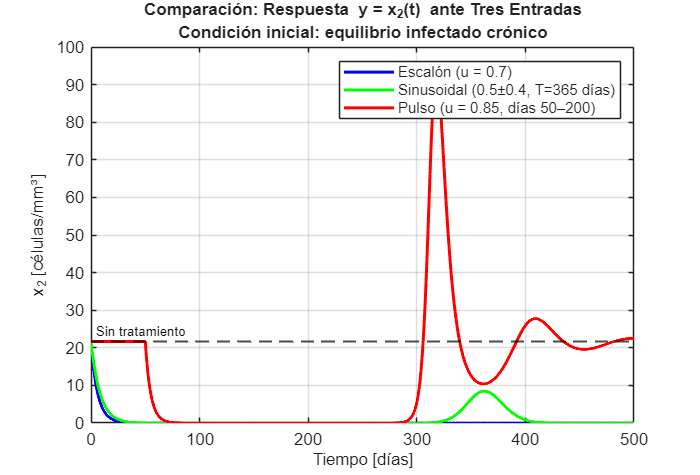

figure('Name','Comparación de respuestas — tres entradas', ...
       'NumberTitle','off','Color','w','Position',[860 380 560 380]);

plot(t1, X1(:,2), 'b', 'LineWidth', 1.8); hold on;
plot(t2, X2(:,2), 'g', 'LineWidth', 1.8);
plot(t3, X3(:,2), 'r', 'LineWidth', 1.8);
yline(y_eq_inf, '--k', 'LineWidth', 1.2, ...
      'Label', 'Sin tratamiento', 'LabelHorizontalAlignment', 'left', 'FontSize', 8);
hold off;

xlabel('Tiempo [días]', 'FontSize', 10);
ylabel('x_2 [células/mm³]', 'FontSize', 10);
title({'Comparación: Respuesta  y = x_2(t)  ante Tres Entradas'; ...
       'Condición inicial: equilibrio infectado crónico'}, ...
       'FontSize', 10, 'FontWeight', 'bold');
legend({'Escalón (u = 0.7)', ...
        sprintf('Sinusoidal (%.1f±%.1f, T=365 días)', offset, A_sin), ...
        sprintf('Pulso (u = %.2f, días %d–%d)', u_pul, t_ini_p, t_fin_p)}, ...
       'Location', 'northeast', 'FontSize', 9);
grid on; box on;

## 3.2.5 Resumen Numérico de las Tres Respuestas

% Valor mínimo de x₂ alcanzado (menor carga de infectadas)
[x2_min1, idx1] = min(X1(:,2));
[x2_min2, idx2] = min(X2(:,2));
[x2_min3, idx3] = min(X3(:,2));

fprintf('   Condición inicial: equilibrio infectado  x2(0) = %.4f\n', x0_trat(2));

   Condición inicial: equilibrio infectado  x2(0) = 21.6667



Entrada = ["Escalón"; "Sinusoidal"; "Pulso"; "Sin tratamiento"];

x2_min = [x2_min1; x2_min2; x2_min3; 0];
t_min  = [t1(idx1); t2(idx2); t3(idx3); 0];
x2_final = [X1(end,2); X2(end,2); X3(end,2); y_eq_inf];


Resumen = table(Entrada, x2_min, t_min, x2_final, ...
    'VariableNames', {'Entrada','x2_min_cel_mm3','t_x2_min_dias','x2_final_cel_mm3'});

Resumen

Resumen = 4×4 table
         Entrada         x2_min_cel_mm3    t_x2_min_dias    x2_final_cel_mm3
    _________________    ______________    _____________    ________________

    "Escalón"              1.0685e-20            500           1.0685e-20   
    "Sinusoidal"           2.0677e-10         180.71           4.1979e-08   
    "Pulso"                5.2764e-11         200.11               22.512   
    "Sin tratamiento"               0              0               21.667   


## 3.3 Simulación con el Cambio de Dos Parámetros

Se estudia el efecto de variar los parámetros β (coeficiente de infección) y μ (tasa de muerte de células infectadas) sobre la respuesta temporal de la salida y = x₂(t).

Estos dos parámetros se seleccionan porque:

- **β** controla directamente la velocidad a la que el virus se propaga. Varía entre pacientes según su cepa viral y factores inmunológicos.

- **μ** determina cuánto tiempo viven las células infectadas. Una μ mayor significa que las células infectadas mueren más rápido, lo que limita la producción de nuevos viriones.

**Escenario de simulación:** se parte de la persona sana recién infectada (x₀ = [500; 0.024]), sin tratamiento (u = 0), durante 800 días. Este escenario maximiza la diferencia visible entre valores del parámetro porque cada valor produce un equilibrio infectado distinto.

**Tres características de la respuesta temporal extraídas:**

- **Valor pico de x₂** — máxima concentración de células infectadas durante el transitorio [células/mm³].

- **Tiempo al pico** — día en que x₂ alcanza su valor máximo [días].

- **Valor en estado estacionario** — valor de x₂ al final de la simulación, aproximación al equilibrio infectado crónico [células/mm³].

% Condiciones iniciales y horizonte comunes a todo el análisis paramétrico
x0_param = [s/d;  (c/k)*1];   % Persona sana + 1 virión/mm³
t_param   = 800;               % Horizonte de simulación [días]
u_param   = 0;                 % Sin tratamiento

## 3.3.1 Variación del Parámetro β (Coeficiente de Infección)

Se evalúan cinco valores de β distribuidos alrededor del valor nominal, cubriendo un rango biológicamente razonable de variación inter-paciente.

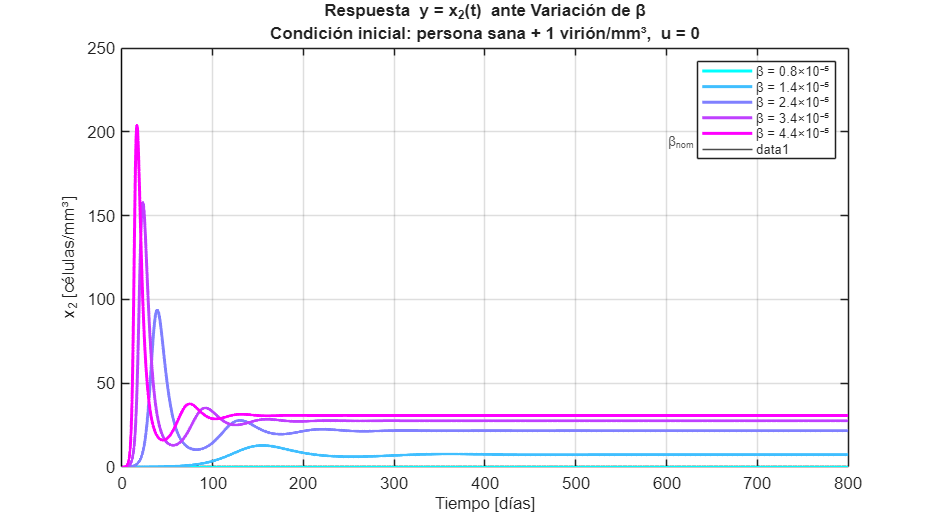

beta_vals = [0.8, 1.4, 2.4, 3.4, 4.4] * 1e-5;   % [mm³/día]
beta_nom  = beta;                                   % Valor nominal para referencia

% Etiquetas para gráficos y tablas
beta_labels = arrayfun(@(b) sprintf('β = %.1f×10⁻⁵', b*1e5), beta_vals, ...
                        'UniformOutput', false);

% Matrices de almacenamiento de resultados
n_vals   = length(beta_vals);
pico_b   = zeros(1, n_vals);    % Valor pico de x₂  [células/mm³]
t_pico_b = zeros(1, n_vals);    % Tiempo al pico     [días]
xss_b    = zeros(1, n_vals);    % Valor estacionario [células/mm³]

% Figura: respuesta temporal con cinco valores de β
figure('Name','Variación de β — Respuesta temporal de x₂', ...
       'NumberTitle','off','Color','w','Position',[100 80 750 420]);

colores_b = cool(n_vals);   % Paleta fría: azul (β bajo) → magenta (β alto)
hold on;

for i = 1:n_vals
    bi   = beta_vals(i);
    bkci = bi * k / c;    % Término compuesto β_i·k/c para este valor

    % Sistema con β variable, resto de parámetros nominales
    ode_bi = @(t, x) [
        s - d*x(1) - (1 - u_param)*bkci*x(1)*x(2);
        (1 - u_param)*bkci*x(1)*x(2) - mu*x(2)
    ];

    [ti, Xi] = ode45(ode_bi, [0 t_param], x0_param, opts);

    % Extraer características
    [pico_b(i), idx_p]  = max(Xi(:,2));
    t_pico_b(i)         = ti(idx_p);
    xss_b(i)            = Xi(end, 2);

    plot(ti, Xi(:,2), 'Color', colores_b(i,:), 'LineWidth', 1.8);
end

hold off;
xlabel('Tiempo [días]',        'FontSize', 10);
ylabel('x_2 [células/mm³]',   'FontSize', 10);
title({'Respuesta  y = x_2(t)  ante Variación de β'; ...
       'Condición inicial: persona sana + 1 virión/mm³,  u = 0'}, ...
       'FontSize', 10, 'FontWeight', 'bold');
legend(beta_labels, 'Location', 'northeast', 'FontSize', 8);
grid on; box on;

% Anotación del valor nominal
xline(0, 'k', 'LineWidth', 0.5);   % Solo para activar el grid
text(600, max(pico_b)*0.95, sprintf('β_{nom} = 2.4×10⁻⁵'), ...
     'FontSize', 8, 'Color', [0.3 0.3 0.3], 'HorizontalAlignment', 'left');

## 3.3.2 Tabla de Características — Variación de β

fprintf('\n=================================================================\n');

fprintf('  TABLA 1 — Características de y = x₂(t) al variar β\n');

  TABLA 1 — Características de y = x₂(t) al variar β


fprintf('  Escenario: u = 0, x0 = [%.0f; %.4f], t_sim = %d días\n', ...
        x0_param(1), x0_param(2), t_param);

  Escenario: u = 0, x0 = [500; 0.0240], t_sim = 800 días


fprintf('=================================================================\n');

fprintf('%-22s  %-20s  %-18s  %-20s\n', ...
        'β [mm³/día]', 'Pico x₂ [cél/mm³]', 'Tiempo pico [d]', 'x₂ estac. [cél/mm³]');

β [mm³/día]             Pico x₂ [cél/mm³]     Tiempo pico [d]     x₂ estac. [cél/mm³] 


fprintf('%s\n', repmat('-', 1, 82));

----------------------------------------------------------------------------------


for i = 1:n_vals
    fprintf('%-22s  %-20.4f  %-18.1f  %-20.4f\n', ...
            sprintf('%.1e', beta_vals(i)), pico_b(i), t_pico_b(i), xss_b(i));
end

8.0e-06                 0.0240                0.0                 0.0000              
1.4e-05                 12.8613               154.9               7.3828              
2.4e-05                 93.6939               39.0                21.6667             
3.4e-05                 157.6820              23.1                27.5490             
4.4e-05                 203.7967              16.6                30.7576             


fprintf('=================================================================\n');

## 3.3.3 Gráfico de Características vs β

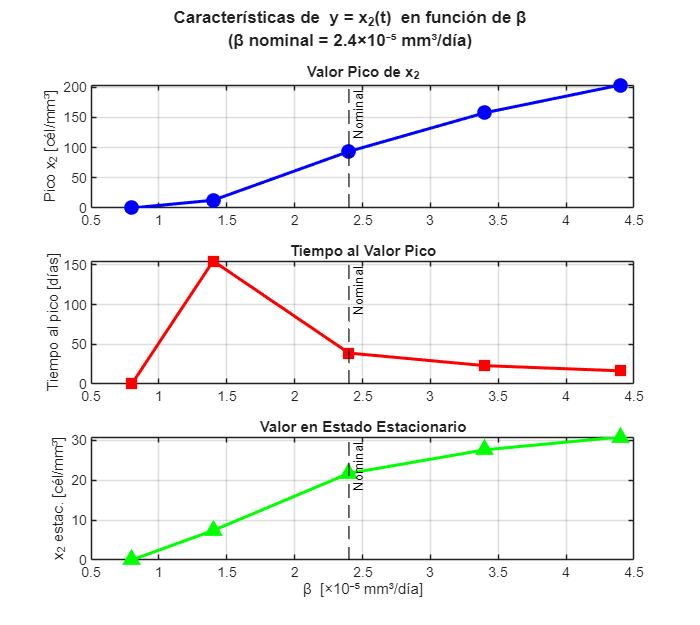

figure('Name','Características de la respuesta vs β', ...
       'NumberTitle','off','Color','w','Position',[860 80 560 500]);

beta_plot = beta_vals * 1e5;   % Escalar a ×10⁻⁵ para el eje x

subplot(3,1,1);
plot(beta_plot, pico_b, 'bo-', 'LineWidth', 1.8, 'MarkerFaceColor', 'b', 'MarkerSize', 7);
xline(beta_nom*1e5, '--k', 'LineWidth', 1.0, 'Label', 'Nominal', ...
      'LabelHorizontalAlignment', 'right', 'FontSize', 8);
ylabel('Pico x_2 [cél/mm³]', 'FontSize', 9);
title('Valor Pico de x_2', 'FontSize', 9, 'FontWeight', 'bold');
grid on; box on;

subplot(3,1,2);
plot(beta_plot, t_pico_b, 'rs-', 'LineWidth', 1.8, 'MarkerFaceColor', 'r', 'MarkerSize', 7);
xline(beta_nom*1e5, '--k', 'LineWidth', 1.0, 'Label', 'Nominal', ...
      'LabelHorizontalAlignment', 'right', 'FontSize', 8);
ylabel('Tiempo al pico [días]', 'FontSize', 9);
title('Tiempo al Valor Pico', 'FontSize', 9, 'FontWeight', 'bold');
grid on; box on;

subplot(3,1,3);
plot(beta_plot, xss_b, 'g^-', 'LineWidth', 1.8, 'MarkerFaceColor', 'g', 'MarkerSize', 7);
xline(beta_nom*1e5, '--k', 'LineWidth', 1.0, 'Label', 'Nominal', ...
      'LabelHorizontalAlignment', 'right', 'FontSize', 8);
xlabel('β  [×10⁻⁵ mm³/día]', 'FontSize', 9);
ylabel('x_2 estac. [cél/mm³]', 'FontSize', 9);
title('Valor en Estado Estacionario', 'FontSize', 9, 'FontWeight', 'bold');
grid on; box on;

sgtitle({'Características de  y = x_2(t)  en función de β'; ...
         '(β nominal = 2.4×10⁻⁵ mm³/día)'}, ...
         'FontSize', 10, 'FontWeight', 'bold');

## 3.3.4 Variación del Parámetro μ (Tasa de Muerte de Células Infectadas)

Se evalúan cinco valores de μ distribuidos alrededor del valor nominal. Una μ mayor implica células infectadas más cortas de vida: producen menos virus en total antes de morir, lo que atenúa la infección.

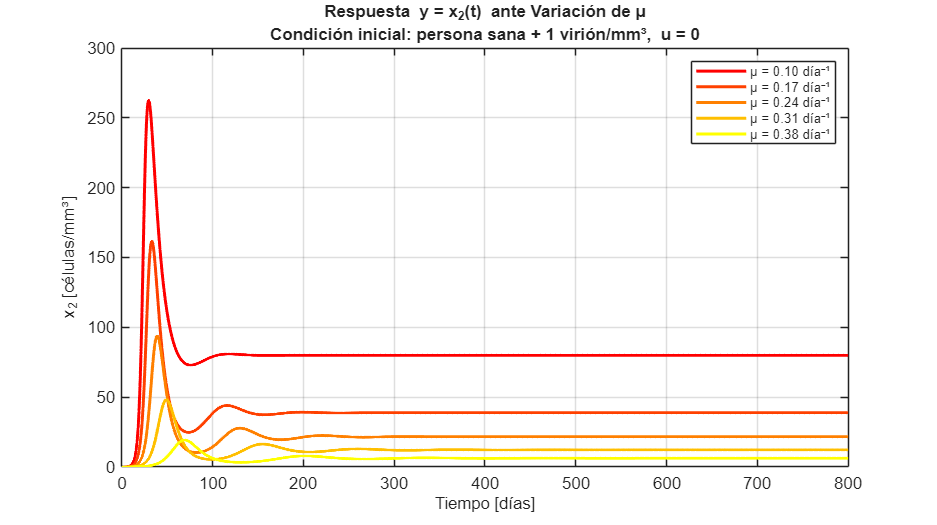

mu_vals   = [0.10, 0.17, 0.24, 0.31, 0.38];   % [día⁻¹]
mu_nom    = mu;                                  % Valor nominal para referencia

mu_labels = arrayfun(@(m) sprintf('μ = %.2f día⁻¹', m), mu_vals, ...
                      'UniformOutput', false);

% Matrices de almacenamiento
pico_m   = zeros(1, n_vals);
t_pico_m = zeros(1, n_vals);
xss_m    = zeros(1, n_vals);

% Figura: respuesta temporal con cinco valores de μ
figure('Name','Variación de μ — Respuesta temporal de x₂', ...
       'NumberTitle','off','Color','w','Position',[100 540 750 420]);

colores_m = autumn(n_vals);   % Paleta cálida: rojo (μ bajo) → amarillo (μ alto)
hold on;

for i = 1:n_vals
    mu_i = mu_vals(i);

    % Sistema con μ variable, resto de parámetros nominales
    ode_mi = @(t, x) [
        s - d*x(1) - (1 - u_param)*bkc*x(1)*x(2);
        (1 - u_param)*bkc*x(1)*x(2) - mu_i*x(2)
    ];

    [ti, Xi] = ode45(ode_mi, [0 t_param], x0_param, opts);

    % Extraer características
    [pico_m(i), idx_p]  = max(Xi(:,2));
    t_pico_m(i)         = ti(idx_p);
    xss_m(i)            = Xi(end, 2);

    plot(ti, Xi(:,2), 'Color', colores_m(i,:), 'LineWidth', 1.8);
end

hold off;
xlabel('Tiempo [días]',       'FontSize', 10);
ylabel('x_2 [células/mm³]',  'FontSize', 10);
title({'Respuesta  y = x_2(t)  ante Variación de μ'; ...
       'Condición inicial: persona sana + 1 virión/mm³,  u = 0'}, ...
       'FontSize', 10, 'FontWeight', 'bold');
legend(mu_labels, 'Location', 'northeast', 'FontSize', 8);
grid on; box on;

## 3.3.5 Tabla de Características — Variación de μ

fprintf('\n=================================================================\n');

fprintf('  TABLA 2 — Características de y = x₂(t) al variar μ\n');

  TABLA 2 — Características de y = x₂(t) al variar μ


fprintf('  Escenario: u = 0, x0 = [%.0f; %.4f], t_sim = %d días\n', ...
        x0_param(1), x0_param(2), t_param);

  Escenario: u = 0, x0 = [500; 0.0240], t_sim = 800 días


fprintf('=================================================================\n');

fprintf('%-20s  %-20s  %-18s  %-20s\n', ...
        'μ [día⁻¹]', 'Pico x₂ [cél/mm³]', 'Tiempo pico [d]', 'x₂ estac. [cél/mm³]');

μ [día⁻¹]             Pico x₂ [cél/mm³]     Tiempo pico [d]     x₂ estac. [cél/mm³] 


fprintf('%s\n', repmat('-', 1, 80));

--------------------------------------------------------------------------------


for i = 1:n_vals
    fprintf('%-20.2f  %-20.4f  %-18.1f  %-20.4f\n', ...
            mu_vals(i), pico_m(i), t_pico_m(i), xss_m(i));
end

0.10                  262.4117              29.5                80.0000             
0.17                  161.4971              33.0                38.8235             
0.24                  93.6939               39.0                21.6667             
0.31                  48.1054               49.1                12.2582             
0.38                  19.2990               69.3                6.3152              


fprintf('=================================================================\n');

## 3.3.6 Gráfico de Características vs μ

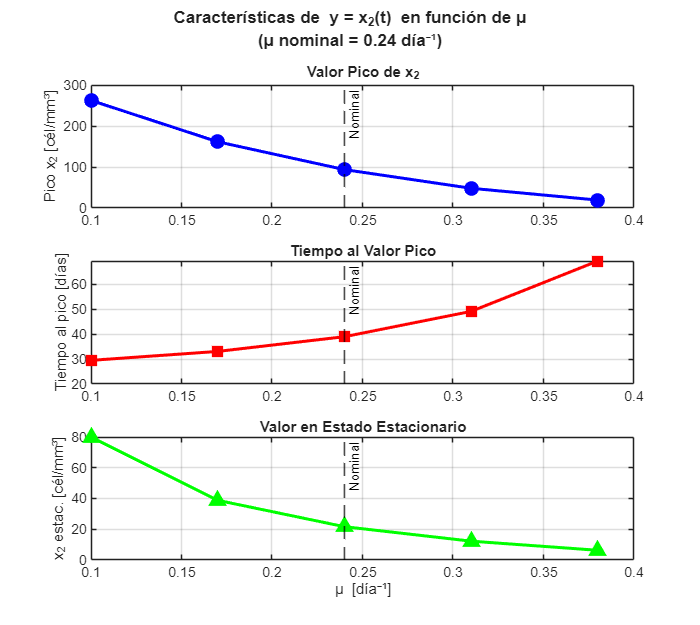

figure('Name','Características de la respuesta vs μ', ...
       'NumberTitle','off','Color','w','Position',[860 540 560 500]);

subplot(3,1,1);
plot(mu_vals, pico_m, 'bo-', 'LineWidth', 1.8, 'MarkerFaceColor', 'b', 'MarkerSize', 7);
xline(mu_nom, '--k', 'LineWidth', 1.0, 'Label', 'Nominal', ...
      'LabelHorizontalAlignment', 'right', 'FontSize', 8);
ylabel('Pico x_2 [cél/mm³]', 'FontSize', 9);
title('Valor Pico de x_2', 'FontSize', 9, 'FontWeight', 'bold');
grid on; box on;

subplot(3,1,2);
plot(mu_vals, t_pico_m, 'rs-', 'LineWidth', 1.8, 'MarkerFaceColor', 'r', 'MarkerSize', 7);
xline(mu_nom, '--k', 'LineWidth', 1.0, 'Label', 'Nominal', ...
      'LabelHorizontalAlignment', 'right', 'FontSize', 8);
ylabel('Tiempo al pico [días]', 'FontSize', 9);
title('Tiempo al Valor Pico', 'FontSize', 9, 'FontWeight', 'bold');
grid on; box on;

subplot(3,1,3);
plot(mu_vals, xss_m, 'g^-', 'LineWidth', 1.8, 'MarkerFaceColor', 'g', 'MarkerSize', 7);
xline(mu_nom, '--k', 'LineWidth', 1.0, 'Label', 'Nominal', ...
      'LabelHorizontalAlignment', 'right', 'FontSize', 8);
xlabel('μ  [día⁻¹]', 'FontSize', 9);
ylabel('x_2 estac. [cél/mm³]', 'FontSize', 9);
title('Valor en Estado Estacionario', 'FontSize', 9, 'FontWeight', 'bold');
grid on; box on;

sgtitle({'Características de  y = x_2(t)  en función de μ'; ...
         '(μ nominal = 0.24 día⁻¹)'}, ...
         'FontSize', 10, 'FontWeight', 'bold');

## 4. Discusión y Conclusiones

## **4.1 Verificación del Modelo**

La simulación reproduce correctamente el comportamiento descrito en el artículo de referencia. Partiendo de una persona sana que se infecta con una partícula viral, el modelo muestra cómo las células sanas caen de 500 a 240 células/mm³ y las infectadas suben hasta estabilizarse en aproximadamente 21.67 células/mm³, valores que coinciden con los reportados por Barão & Lemos (2007) con un error menor al 0.01%. El plano de fase confirma que sin importar desde dónde empiece la infección, el sistema siempre termina convergiendo al mismo punto de equilibrio infectado, describiendo una espiral característica de este tipo de sistemas biológicos. Esto valida que la implementación es correcta y que el modelo captura bien la realidad clínica.

## **4.2 Simulación con Entrada Escalón**

Cuando el paciente inicia un tratamiento continuo con 70% de eficacia, la concentración de células infectadas baja de forma sostenida hasta un nuevo nivel estable, significativamente menor que sin tratamiento. Este resultado era esperado: el medicamento reduce la probabilidad de que el virus infecte nuevas células, por lo que el sistema encuentra un nuevo equilibrio con menos infección. La conclusión clínica es clara: un tratamiento constante y bien administrado sí logra mantener la infección bajo control indefinidamente, aunque sin eliminarla por completo.

## **4.3 Simulación con Entrada Sinusoidal**

Con un tratamiento que varía de forma periódica, simulando adherencia irregular, la concentración de células infectadas nunca se estabiliza: sube y baja siguiendo el ritmo del medicamento. En los períodos de alta eficacia la infección retrocede, pero en los de baja eficacia avanza de nuevo. El resultado neto es que el paciente nunca alcanza un nivel bajo y estable de infección. Esto ilustra de forma muy directa por qué la adherencia regular al tratamiento antirretroviral es tan importante: la irregularidad impide que el cuerpo consolide la mejora.

## **4.4 Simulación con Entrada Pulso**

El tratamiento intensivo de 150 días con 85% de eficacia logra reducir considerablemente la infección durante su aplicación. Sin embargo, al suspenderlo, las células infectadas rebotan y el sistema regresa al mismo equilibrio crónico de antes. Esto ocurre porque el virus no desaparece durante el tratamiento, solo se suprime temporalmente. Al retirar el medicamento, la dinámica de infección se reactiva. Este comportamiento, conocido clínicamente como rebote viral, es consistente con lo que se observa en pacientes reales que interrumpen la terapia, y confirma que el tratamiento debe ser continuo para mantener su efecto.

## **4.5 Variación del Parámetro β**

Al aumentar β, que representa qué tan fácil es que el virus infecte una célula sana, la infección es más severa en todos los sentidos: la concentración de células infectadas sube más alto, el pico se alcanza más rápido y el nivel estable final es mayor. Con valores bajos de β la infección progresa despacio y se estabiliza en niveles relativamente bajos; con valores altos el deterioro inmune es mucho más rápido y pronunciado. En la práctica, este parámetro varía entre pacientes según la cepa viral, lo que explica por qué algunas personas progresan hacia el SIDA más rápido que otras.

## **4.6 Variación del Parámetro μ**

Al aumentar μ, que representa qué tan rápido mueren las células infectadas, la infección resulta menos grave: el pico de células infectadas es más bajo y el nivel estable final también. Cuando las células infectadas mueren rápido, producen menos virus antes de desaparecer, lo que frena la propagación. Es el efecto contrario al de β: si β es el acelerador de la infección, μ actúa como su freno natural. Es interesante notar que ambos parámetros acortan el tiempo al pico cuando aumentan, pero por razones distintas: β porque acelera la infección, μ porque acelera la resolución del transitorio.

## **4.7 Conclusiones**

El modelo de VIH-1 estudiado demuestra ser una herramienta sencilla pero poderosa para entender la dinámica de la infección. Las simulaciones muestran que el tratamiento antirretroviral puede controlar eficazmente la carga infecciosa, pero solo si se mantiene de forma continua y consistente. Un tratamiento irregular o interrumpido no logra estabilizar al paciente en un nivel bajo de infección. Por otro lado, la variación de los parámetros biológicos revela que la agresividad de la infección depende fuertemente de características propias del virus (β) y del sistema inmune del paciente (μ), lo que ayuda a entender la diversidad clínica que se observa entre distintos pacientes con VIH.

## Referencias

[1] Barão, M., & Lemos, J. M. (2007). Nonlinear control of HIV-1 infection with a singular perturbation model. *Biomedical Signal Processing and Control*, 2(3), 248–257. [https://doi.org/10.1016/j.bspc.2007.07.011](https://doi.org/10.1016/j.bspc.2007.07.011)